## Drive mathematical model

% Time [s]
syms t

% Signals: current [A], angular velocity [rad/s], voltage [V]
syms i(t) w(t) u(t) 

% Parameters: rotor inertia [kg*m^2], back-EMF constant [V/(rad/s)]=[Nm*A]
% armature inductance [H], resistance [Ohm],
syms Jm Ke La Ra 

% Input voltage
Vn = 6; % [V]

DriveModelEq = [
% ------------------------------------------------------------------------- %

    % Kirchhoff's current law for DC motor equivalent circuit 
    u(t) == Ke*w(t) + Ra*i(t) + La*diff(i(t))

    % Newton's second law for rotational motion 
    Ke*i(t) == Jm*diff(w(t)) % + b*w(t)

% ------------------------------------------------------------------------- %
]

$$DriveModelEq = \left(\begin{array}{c} u\left(t\right)=\mathrm{La}\,\frac{\partial }{\partial t}i\left(t\right)+\mathrm{Ra}\,i\left(t\right)+\mathrm{Ke}\,w\left(t\right)\\ \mathrm{Ke}\,i\left(t\right)=\mathrm{Jm}\,\frac{\partial }{\partial t}w\left(t\right) \end{array}\right)$$


% Derive an analytical formula for the step response  
syms i_ w_ dwdt
sig_algb = {i_,   dwdt};        % {i_,   w_,   dwdt}                    
sig_diff = {i(t), diff(w(t))};  % {i(t), w(t), diff(w(t))}

%#1 Solve 2nd eq. for i(t) and substitute for it in 1st eq.
eq_tmp = subs(DriveModelEq(2), sig_diff, sig_algb);            
eq_tmp = subs(DriveModelEq(1), i(t), subs(solve(eq_tmp, i_), sig_algb, sig_diff));    

syms s I(s) W(s) U(s) W_ U_
tr_diff = {laplace(i(t),t,s), laplace(w(t),t,s), laplace(u(t),t,s)};
tr_s = {I(s), W(s), U(s)};

%#2 Calculate the Laplace transform of modfied 1st eq.
eq_tmp = subs(laplace(eq_tmp, t, s),  tr_diff, tr_s);

%#3 Asume zero initial condition for transfer function model
sig_init = {i(0), w(0), subs(diff(w(t), t), t, 0)};
eq_tmp = subs(eq_tmp, sig_init, {0, 0, 0});

%#4 Calculate W(s)/U(s) transfer function model 
DriveModelTf = 1 / collect(solve(subs(eq_tmp, {W(s), U(s)}, {W_, U_}), U_) / W_) % * LPF(s)

$$DriveModelTf = \frac{1}{\frac{\mathrm{Jm}\,\mathrm{La}}{\mathrm{Ke}}\,s^{2}+\frac{\mathrm{Jm}\,\mathrm{Ra}}{\mathrm{Ke}}\,s+\mathrm{Ke}}$$

% Drive step response analityc function
DriveModelTf_StepResponse = ilaplace(Vn*DriveModelTf/s, s, t)

$$DriveModelTf\_StepResponse = \begin{array}{l} \frac{6}{\mathrm{Ke}}-\frac{6\,{\mathrm{e}}^{-\frac{\mathrm{Ra}\,t}{2\,\mathrm{La}}}\,\left(\cosh\left(\sigma_{1}\right)+\frac{\sqrt{\mathrm{Jm}}\,\mathrm{Ra}\,\sinh\left(\sigma_{1}\right)}{2\,\sqrt{\frac{\mathrm{Jm}\,{\mathrm{Ra}}^{2}}{4}-{\mathrm{Ke}}^{2}\,\mathrm{La}}}\right)}{\mathrm{Ke}}\\ \mathrm{where}\\ \sigma_{1}=\frac{t\,\sqrt{\frac{\mathrm{Jm}\,{\mathrm{Ra}}^{2}}{4}-{\mathrm{Ke}}^{2}\,\mathrm{La}}}{\sqrt{\mathrm{Jm}}\,\mathrm{La}} \end{array}$$


clear i_ w_ dwdt I(s) W(s) U(s) W_ U_ 

% Symbolic formula to MATLAB function handle
DriveModelTf_StepResponse = matlabFunction(DriveModelTf_StepResponse);


## Experimental results

load('step_02_syntetic_experimental_data.mat')

## Parametric identification of drive model

objFcn = @(x)(mse(w_exp - DriveModelTf_StepResponse(x(1), x(2), x(3), x(4), t_exp))/length(t_exp));

x_init = [
    1e-7  ... % rotor inertia [kg*m^2], 
    1e-3  ... % back-EMF constant [V/(rad/s)]=[Nm*A]
    1e-4  ... % armature inductance [H]
    0.7   ... % resistance [Ohm]
];

[x, fval, exitflag, output] = fmincon(objFcn, x_init.*randn(1,4),[],[],[],[],x_init/100,x_init*100)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.0000    0.0017    0.0019    0.1838


fval = 0.0487

exitflag = 2

output = struct with fields:
         iterations: 20
          funcCount: 175
    constrviolation: 0
           stepsize: 5.6258e-11
          algorithm: 'interior-point'
      firstorderopt: 371.0411
       cgiterations: 54
            message: '↵Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-10, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵'
       bestfeasible: [1×1 struct]


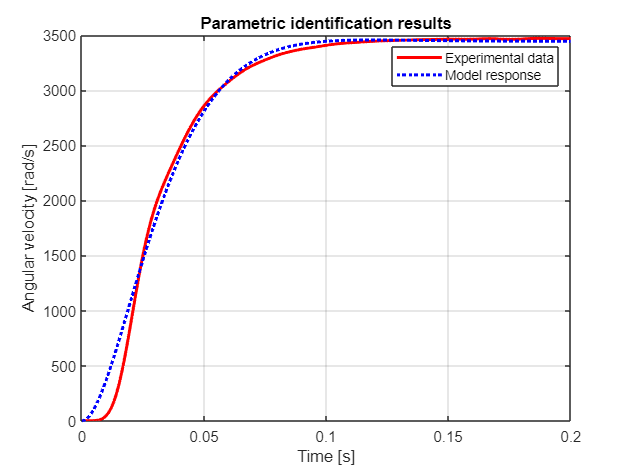


plot(t_exp, w_exp, 'r', 'LineWidth', 2, 'DisplayName', 'Experimental data');
hold on;
plot(t_exp, DriveModelTf_StepResponse(x(1), x(2), x(3), x(4), t_exp), 'b:', 'LineWidth', 2, 'DisplayName', 'Model response');
xlabel('Time [s]');
ylabel('Angular velocity [rad/s]');
grid on;
title('Parametric identification results')
legend();
hold off;


printout = ['Rotor inertia: ' num2str(x(1)) ' [kg*m^2]\n' ... 
            'Back-EMF constant: ' num2str(x(2)) ' [V/(rad/s)]=[Nm*A]\n' ...
            'Armature inductance: ' num2str(x(3)) ' [H]\n' ...
            'Armature resistance: ' num2str(x(4)) ' [Ohm]\n' ...
            'Stall torque: ' num2str(x(2)*Vn/x(4)) ' [Nm]\n' ...
            'No load speed: ' num2str(Vn/x(2)) ' [rad/s]\n'];
fprintf(printout);

Rotor inertia: 5.3e-07 [kg*m^2]
Back-EMF constant: 0.001742 [V/(rad/s)]=[Nm*A]
Armature inductance: 0.0019253 [H]
Armature resistance: 0.18383 [Ohm]
Stall torque: 0.056859 [Nm]
No load speed: 3444.2338 [rad/s]
